#### тест1

n=2;
e = ones(n,1);
H = [1 2
     2 3.9999];
b = [4;7.9999];
disp('condH');

condH


cond(H)

ans = 2.4999e+05

x_lu = LUsolver(H,b);
x_qr = QRsolver(H,b);
norm(x_lu - e)

ans = 1.0000

norm(x_qr - e)

ans = 1.0000

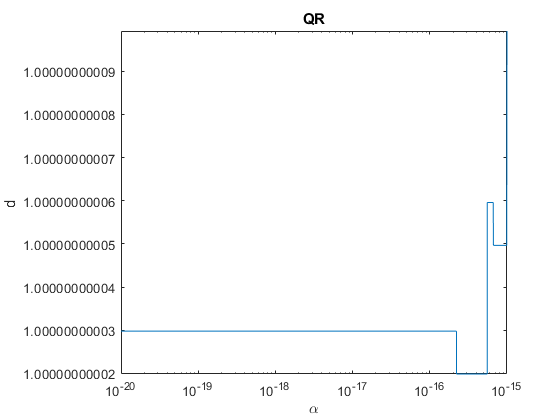

alpha = 1e-20;
E = eye(n);
d = zeros(1e5,1);
for i = 1:1e5
    A = H + alpha*i*E;
    x = QRsolver(A,b);
    d(i) = norm(x - e);
end
semilogx(alpha*(1:1e5),d);
title('QR');
xlabel('$\alpha$','Interpreter',"latex");
ylabel('d');

[m,i] = min(d);
disp('Минимум при альфа:');

Минимум при альфа:


i*alpha

ans = 2.2205e-16

disp('Который равен:');

Который равен:


m

m = 1.0000

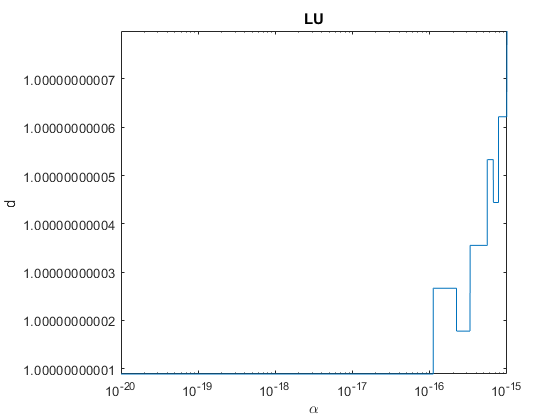

alpha = 1e-20;
E = eye(n);
d = zeros(1e5,1);
for i = 1:1e5
    A = H + alpha*i*E;
    x = LUsolver(A,b);
    d(i) = norm(x - e);
end
semilogx(alpha*(1:1e5),d);
title('LU');
xlabel('$\alpha$','Interpreter',"latex");
ylabel('d');

[m,i] = min(d);
disp('Минимум при альфа:');

Минимум при альфа:


i*alpha

ans = 1.0000e-20

disp('Который равен:');

Который равен:


m

m = 1.0000

#### тест2

n=4;
epsil0=1e-20;
e = ones(n,1);
H = [3+epsil0 3 2 1
     3 2+epsil0 2 1
     2 2 1+epsil0 1
     1 1 1 epsil0 ];
b = [4;3;2;1];
disp('condH');

condH


cond(H)

ans = 2.5080e+16

x_lu = LUsolver(H,b);
x_qr = QRsolver(H,b);
norm(x_lu - e)

ans = 7.8001e+15

norm(x_qr - e)

ans = 1.8014e+16

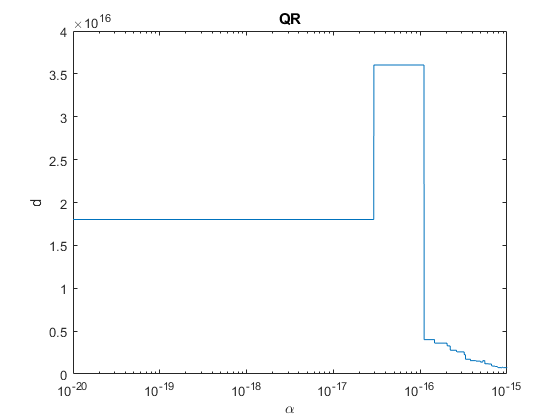

alpha = 1e-20;
E = eye(n);
d = zeros(1e5,1);
for i = 1:1e5
    A = H + alpha*i*E;
    x = QRsolver(A,b);
    d(i) = norm(x - e);
end
semilogx(alpha*(1:1e5),d);
title('QR');
xlabel('$\alpha$','Interpreter',"latex");
ylabel('d');

[m,i] = min(d);
disp('Минимум при альфа:');

Минимум при альфа:


i*alpha

ans = 9.9921e-16

disp('Который равен:');

Который равен:


m

m = 6.7979e+14

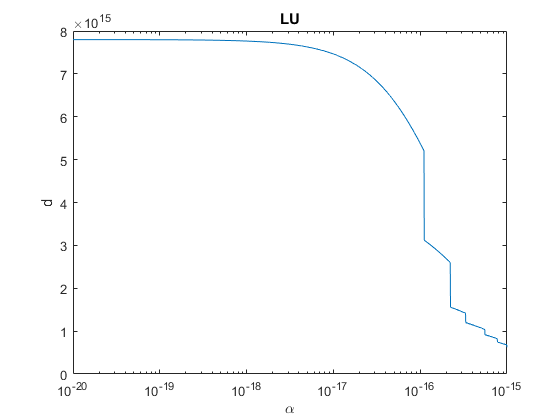

alpha = 1e-20;
E = eye(n);
d = zeros(1e5,1);
for i = 1:1e5
    A = H + alpha*i*E;
    x = LUsolver(A,b);
    d(i) = norm(x - e);
end
semilogx(alpha*(1:1e5),d);
title('LU');
xlabel('$\alpha$','Interpreter',"latex");
ylabel('d');

[m,i] = min(d);
disp('Минимум при альфа:');

Минимум при альфа:


i*alpha

ans = 1.0000e-15

disp('Который равен:');

Который равен:


m

m = 6.2386e+14

#### тест3

n=2;
epsil=1e-20;
e = ones(n,1);
H = [2 1
    2-epsil 1]

H =      2     1
     2     1


b = [2;1];
disp('condH');

condH


cond(H)

ans = 7.4522e+16

x_lu = LUsolver(H,b);
x_qr = QRsolver(H,b);
norm(x_lu - e)

ans = Inf

norm(x_qr - e)

ans = 7.1208e+15

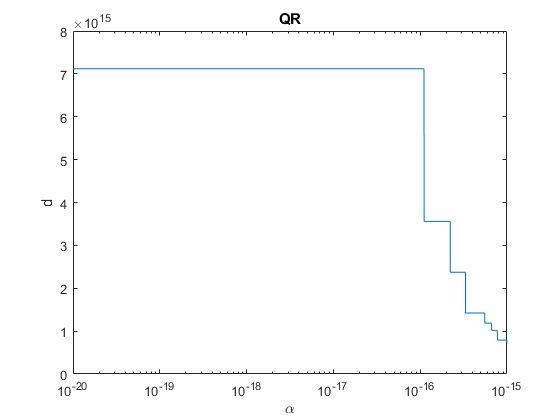

alpha = 1e-20;
E = eye(n);
d = zeros(1e5,1);
for i = 1:1e5
    A = H + alpha*i*E;
    x = QRsolver(A,b);
    d(i) = norm(x - e);
end
semilogx(alpha*(1:1e5),d);
title('QR');
xlabel('$\alpha$','Interpreter',"latex");
ylabel('d');

[m,i] = min(d);
disp('Минимум при альфа:');

Минимум при альфа:


i*alpha

ans = 9.9921e-16

disp('Который равен:');

Который равен:


m

m = 7.1208e+14

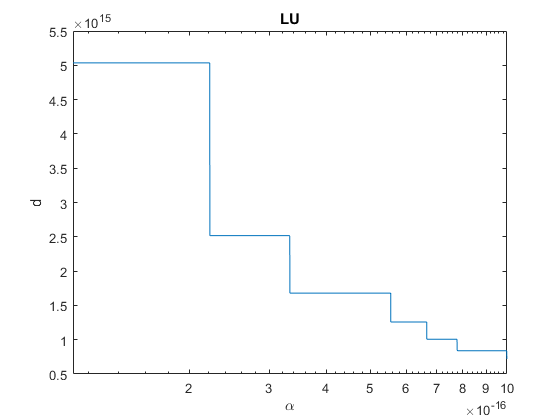

alpha = 1e-20;
E = eye(n);
d = zeros(1e5,1);
for i = 1:1e5
    A = H + alpha*i*E;
    x = LUsolver(A,b);
    d(i) = norm(x - e);
end
semilogx(alpha*(1:1e5),d);
title('LU');
xlabel('$\alpha$','Interpreter',"latex");
ylabel('d');

[m,i] = min(d);
disp('Минимум при альфа:');

Минимум при альфа:


i*alpha

ans = 9.9921e-16

disp('Который равен:');

Который равен:


m

m = 7.1931e+14

## тест4

n=10;
e = ones(n,1);
H = [1 -1 -1 -1 -1 -1 -1 -1 -1 -2
     0 1 -1 -1 -1 -1 -1 -1 -2 -3
     0 0 1 -1 -1 -1 -1 -2 -3 -4
     0 0 0 1 -1 -1 -2 -3 -4 -5
     0 0 0 0 1 -2 -3 -4 -5 -6
     0 0 0 0 0 1 -4 -5 -6 -7 
     0 0 0 0 0 0 1 -6 -7 -8 
     0 0 0 0 0 0 0 1 -8 -9 
     0 0 0 0 0 0 0 0 1 -10 
     0 0 0 0 0 0 0 0 0 1 ];
b = [-9;-8;-7;-6;-5;-4;-3;-2;-1;1];
disp('condH');

condH


cond(H)

ans = 2.8127e+06

x_lu = LUsolver(H,b);
x_qr = QRsolver(H,b);
norm(x_lu - e)

ans = 1.0051e+05

norm(x_qr - e)

ans = 1.0051e+05

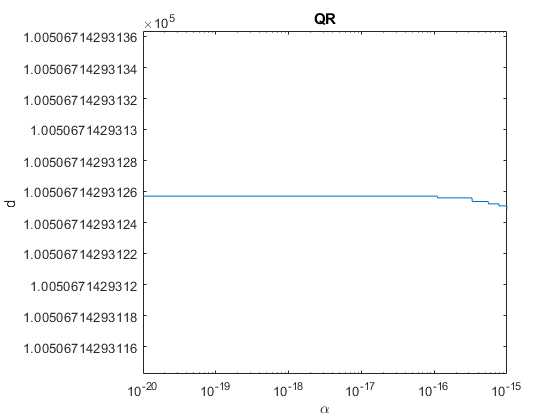

alpha = 1e-20;
E = eye(n);
d = zeros(1e5,1);
for i = 1:1e5
    A = H + alpha*i*E;
    x = QRsolver(A,b);
    d(i) = norm(x - e);
end
semilogx(alpha*(1:1e5),d);
title('QR');
xlabel('$\alpha$','Interpreter',"latex");
ylabel('d');

[m,i] = min(d);
disp('Минимум при альфа:');

Минимум при альфа:


i*alpha

ans = 9.9921e-16

disp('Который равен:');

Который равен:


m

m = 1.0051e+05

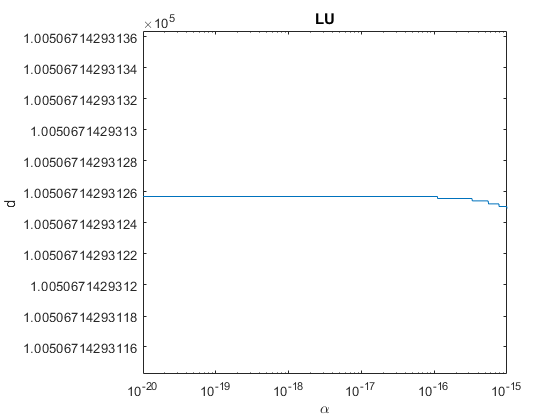

alpha = 1e-20;
E = eye(n);
d = zeros(1e5,1);
for i = 1:1e5
    A = H + alpha*i*E;
    x = LUsolver(A,b);
    d(i) = norm(x - e);
end
semilogx(alpha*(1:1e5),d);
title('LU');
xlabel('$\alpha$','Interpreter',"latex");
ylabel('d');

[m,i] = min(d);
disp('Минимум при альфа:');

Минимум при альфа:


i*alpha

ans = 9.9921e-16

disp('Который равен:');

Который равен:


m

m = 1.0051e+05

### тест5

n = 7;
H = inv(hilb(n));
disp('condH');

condH


cond(H)

ans = 4.7537e+08

e = ones(n,1);
b = H*e;
x_lu = LUsolver(H,b);
x_qr = QRsolver(H,b);
norm(x_lu - e)

ans = 2.5429e-09

norm(x_qr - e)

ans = 3.2470e-09

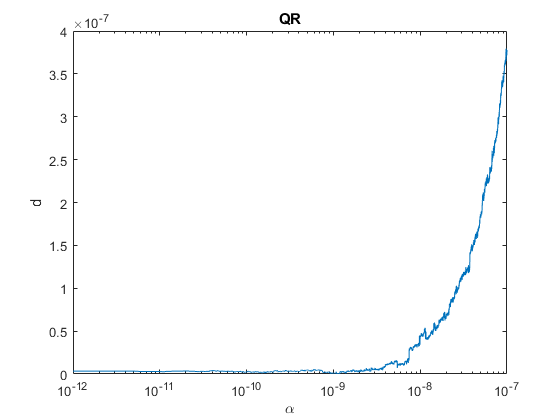

alpha = 1e-12;
E = eye(n);
d = zeros(1e5,1);
for i = 1:1e5
    A = H + alpha*i*E;
    x = QRsolver(A,b);
    d(i) = norm(x - e);
end
semilogx(alpha*(1:1e5),d);
title('QR');
xlabel('$\alpha$','Interpreter',"latex");
ylabel('d');

[m,i] = min(d);
disp('Минимум при альфа:');

Минимум при альфа:


i*alpha

ans = 9.7200e-10

disp('Который равен:');

Который равен:


m

m = 4.4240e-10

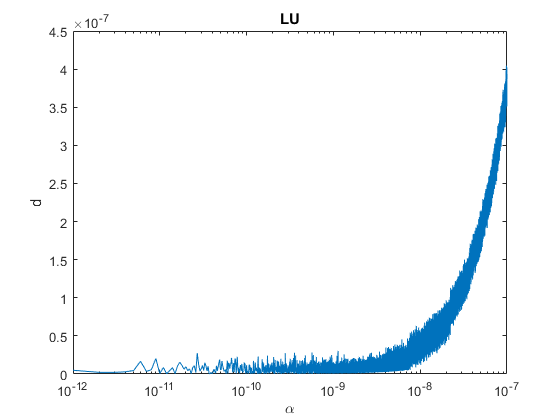

alpha = 1e-12;
E = eye(n);
d = zeros(1e5,1);
for i = 1:1e5
    A = H + alpha*i*E;
    x = LUsolver(A,b);
    d(i) = norm(x - e);
end
semilogx(alpha*(1:1e5),d);
title('LU');
xlabel('$\alpha$','Interpreter',"latex");
ylabel('d');

[m,i] = min(d);
disp('Минимум при альфа:');

Минимум при альфа:


i*alpha

ans = 1.6800e-10

disp('Который равен:');

Который равен:


m

m = 1.0115e-10